# Safety Critical System, Week 10.1: Fault Detection with Parity Method

### Quick review

This lecture focuses on two **model-based, passive** methods to detect faults. 

- Parity: check the consistency of input-output pair (IO). That is, if no fault occurs, the same input must yield the same output, hence residual = 0.

- UIO: *see more in 'asgm2_exc2.mlx'*

In essence, they:

- Require a mathematical model of the plant

- Use only input and output

- Might have strong detectability, weak detectability, or no detectability at all, depending on the fault type.

- On the one hand, if a fault acts on identical channels with disturbance (Eq. 1), there is no way to detect it. Otherwise, we can by simply eliminate states and disturbances (Eq. 2.)

(1) Undetectable fault


$$y=\pmatrix{1 & 0 \cr 0 & 1}x+\pmatrix{0 \cr 1}d+\pmatrix{0 \cr 1}f \\
\Leftrightarrow y_2 = x_2 + d + f$$


(2) Detectable fault


$$y=\pmatrix{1 & 0 \cr 0 & 1}x+\pmatrix{-1 \cr 1}d+\pmatrix{0 \cr 1}f \\
\Leftrightarrow \pmatrix{1 & 1}y = \pmatrix{1 & 1} \pmatrix{1 & 0 \cr 0 & 1}x + \pmatrix{1 & 1} \pmatrix{-1 \cr 1}d +  \pmatrix{1 & 1} \pmatrix{0 \cr 1}f \\
\Leftrightarrow y_1 + y_2 = x_1 + x_2 +0d+1f$$


Multiplying matrix $\pmatrix{1 & 1}$ to the left of $E_x$ helps us eliminate disturbance. Inspired by this idea, "parity method" finds a linear transformation that crosses out everything but fault, returning a residual $r = G_1(f) = G_2(u,y)$.

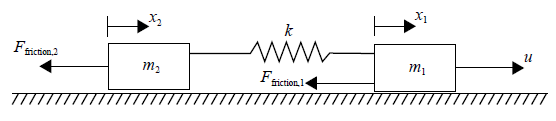

### Exercise 1a: design a residual generator in time domain

m1 = 2;
m2 = 1;
k = 2;
b1 = 3;
b2 = 4;

A = [0 0 1 0;...
     0 0 0 1;...
     -k/m1 k/m1 -b1/m1 0;...
     k/m2 -k/m2 0 -b2/m2];
B = [0; 0; 1/m1; 0];
Ex = [0; 0; 1; 1];
Fx = [0 0;...
      1 0;...
      0 0;...
      0 0];
C = [1 0 0 0;...
     0 1 0 0;...
     1 -1 0 0];
D = zeros([3 1]);
Ey = zeros([3 1]);
Fy = [0 0;...
     0 0;...
     0 1];
X0 = [0; 0; 0; 0]; % Both blocks start from rest

q = 1; % The highest order of our differential equations
O = [C; C*A];
Tuq = [D zeros(size(D, 1), size(D, 2)); C*B D];
Tdq = [Ey zeros(size(Ey, 1), size(Ey, 2)); C*Ex Ey];
Tfq = [Fy zeros(size(Fy, 1), size(Fy, 2)); C*Fx Fy];

Eliminator = [O Tdq];
W = null(Eliminator', 'rational')'

W =     -1     1     1     0     0     0
     0     0     0    -1     1     1



WTfq = W*Tfq % A map from fault to residual

WTfq =      0     1     0     0
     0     0     0     1


### Exercise 1b

According to Eq. 4.4 and 4.5 [1], $r = WT_{f,q}\bar{f}^{(q)}
 $. Since $q=1$, 

$\bar{f}^{(q)} = \bar{f}^{(1)} = \pmatrix{f_1 \cr f_2 \cr \dot{f_1} \cr \dot{f_2}}$; then $r = \pmatrix{0 & 1 & 0 & 0 \cr 0 & 0 & 0 & 1} \pmatrix{f_1 \cr f_2 \cr \dot{f_1} \cr \dot{f_2}}
= \pmatrix{f_2 \cr \dot{f_2}}$

This implies that:

- Fault 2 is strongly detectable, because $r = [f_2; \dot_{f_2}] \neq 0$ as long as fault 2 persists

- Fault 1 is not detectable

### Exercise 1c

Simulations (both in time and frequency domain) are available in the model `asgm2_exc1.slx`. 

Calculation for frequency domain is now quite straightforward (Section 4.2 [1].)

## References

[1] Hossein's lecture notes, Chapter 4: Parity Method.